## **Taylor method** code

0.0000  3.00000000
10.0000 -477.00000000


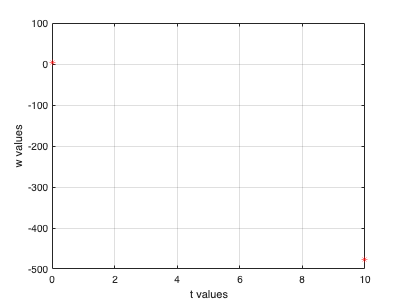

f = @(t,y) (-2*y + 3*exp(t));
fprime=@(t,y) (-4*y + 3*exp(t));
a = 0;
b = 10;
n = 1;
alpha = 3;

h = (b-a)/n;
t=[a zeros(1,n)];
w=[alpha zeros(1,n)];

for i = 1:n+1
t(i+1)=t(i)+h;
wprime=f(t(i),w(i))+(h/2)*fprime(t(i),w(i));
w(i+1)=w(i)+h*wprime;
fprintf('%5.4f %11.8f\n', t(i), w(i));
plot(t(i),w(i),'r*'); grid on;
xlabel('t values'); ylabel('w values');
hold on;
end